# EL2520 Computer Exercise 3

## 4.1 | Suppression of Disturbances

s=tf('s');
G=1e4*(s+2)/(s+3)/(s+100)^2;
Hinf(G);
% create W_S pole pair at p = -0.4 +/- 314.159 in GUI (Gain = 1)

% Note: Before running this section, use the H_inf graphical design tool
% 'Compute controller' and 'export controller' before exiting
Fsim=F;
Gsim=G;
% Edit parameters in macro.m
    % Use sin_dist_freq=100*pi to damp 50hz disturbances

macro

xmin = 0.01;
xmax = 0.2;
subplot(2,2,1)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,2)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,3)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,4)
xlim([xmin xmax])
ylim('auto')

% Find equivalent P controller
% Kp = 20000;
Kp = 17818;
C = pid(Kp,0,0,0,0);
Fsim=C;
Gsim=G;
% Edit parameters in macro.m
    % Use sin_dist_freq=100*pi to damp 50hz disturbances

macro
xmin = 0.05;
xmax = 0.2;
subplot(2,2,1)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,2)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,3)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,4)
xlim([xmin xmax])
ylim('auto')

## 4.2 | Robustness

% Calc delta_G:
% 1 + delta_G = (s-1)/(s+2); [Given]
% delta_G = (s-1)/(s+2) - 1;
% delta_G = (s-1)/(s+2) - (s+2)/(s+2);
% delta_G = (s-1-s-2)/(s+2);

delta_G = -3/(s+2);
G_0 = G*(1+delta_G);

Fsim=F; % Same F computed in 4.1
Gsim=G_0;
% Edit parameters in macro.m
    % Use sin_dist_freq=100*pi to damp 50hz disturbances

macro

xmin = 0.01;
xmax = 10;
subplot(2,2,1)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,2)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,3)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,4)
xlim([xmin xmax])
ylim('auto')


% Small gain theorum: |T(s)| < |1/(dG(s))|
T = inv(1+G*F)*G*F;

figure;
bode(inv(delta_G), T)
grid on
legend('|dG^-1|','|T|');

## Now design controller for T as well

% clear all (command window & outputs)
s=tf('s');
G=1e4*(s+2)/(s+3)/(s+100)^2;
Hinf(G);
% create W_S pole pair at p = -0.4 +/- 314.159 in GUI (Gain = 1)
% Add W_T = delta_G/1000 = -0.003/(s+2)

delta_G = -3/(s+2);
G_0 = G*(1+delta_G);

Fsim=F; % New F computed w.r.t. W_T
Gsim=G_0;
% Edit parameters in macro.m
    % Use sin_dist_freq=100*pi to damp 50hz disturbances

macro

xmin = 0.1;
xmax = 0.3;
subplot(2,2,1)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,2)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,3)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,4)
xlim([xmin xmax])
ylim('auto')

% Small gain theorum: |T(s)| < |1/(dG(s))|
T = inv(1+G*F)*G*F;

figure;
bode(inv(delta_G), T)
grid on
legend('|dG|^-^1','|T|');


## 4.3 | The use of control signal

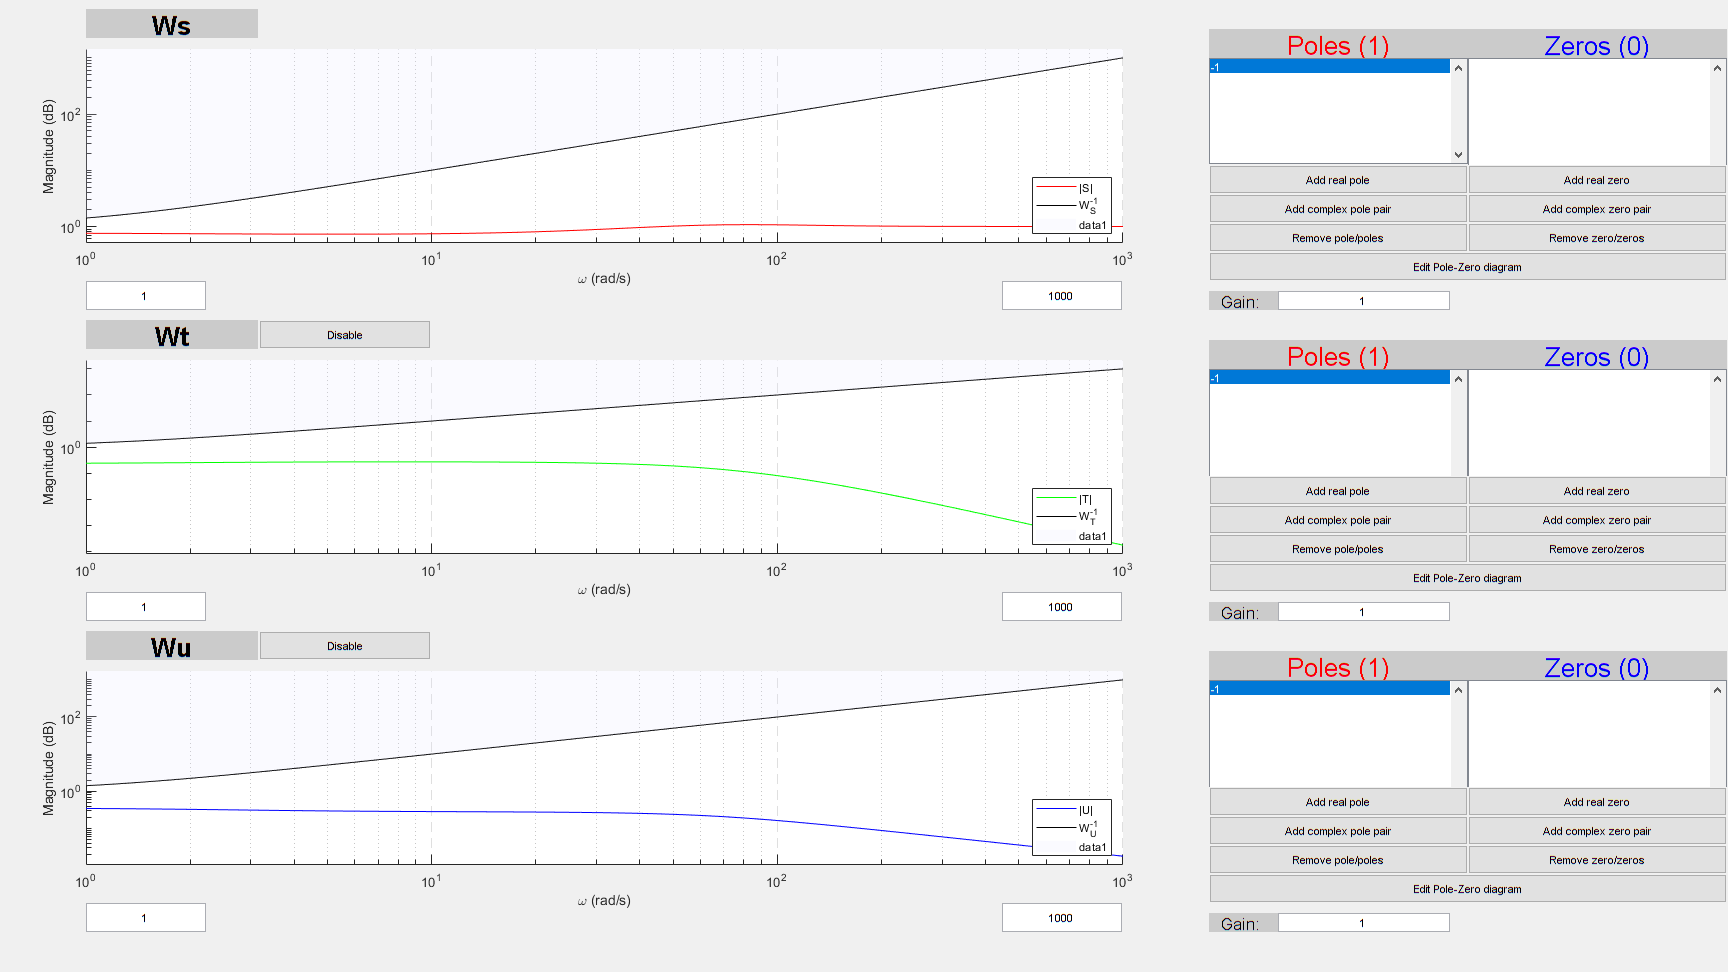

Controller computed successfully
gamma= 0.87448
order: 6


s=tf('s');
G=1e4*(s+2)/(s+3)/(s+100)^2;
Hinf(G);

% create W_S pole pair at p = -0.4 +/- 314.159 in GUI (Gain = 1)
% Add W_T = delta_G/1000 = -0.003/(s+2)
% Add Wu = pole pair at p = -0.2 +/- 314.159 in GUI (Gain = 0.8)


delta_G = -3/(s+2);
G_0 = G*(1+delta_G);

Fsim=F; % New F computed w.r.t. W_T
Gsim=G_0;
% Edit parameters in macro.m
    % Use sin_dist_freq=100*pi to damp 50hz disturbances

macro

y max & min


ans = 13229

ans = 0.5749

ans = -0.5752

u max & min


ans = 4.6914

ans = -4.6902

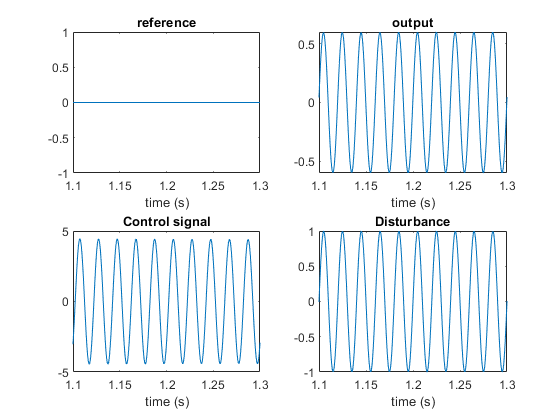


xmin = 1.1;
xmax = 1.3;
subplot(2,2,1)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,2)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,3)
xlim([xmin xmax])
ylim('auto')
subplot(2,2,4)
xlim([xmin xmax])
ylim('auto')

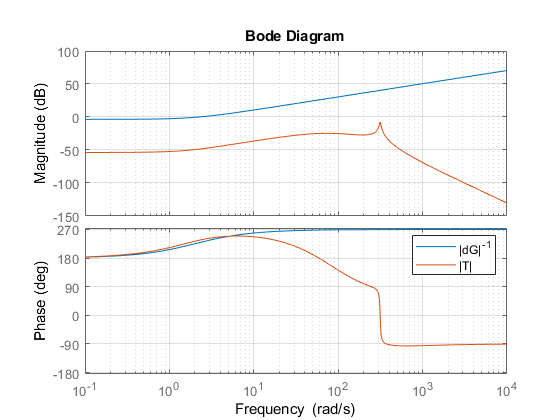


% Small gain theorum: |T(s)| < |1/(dG(s))|
T = inv(1+G*F)*G*F;

figure;
bode(inv(delta_G), T)
grid on
legend('|dG|^-^1','|T|');

% %%%% Saves prior plot as pdf filling up page %%%%
% set(1, 'PaperPosition', [0 0 5 5]); %Position plot at left hand corner with width 5 and height 5.
% set(1, 'PaperSize', [5 5]); %Set the paper to have width 5 and height 5.
% saveas(1, 'test', 'pdf')
% %%%% Saves prior plot as pdf filling up page %%%%